## CA#1

### *Wireless Communication *

### MohammadJavad Javidi

### ID : 810198376

close all; clear; clc;
% Defining parameters
N = 1e5;
D = 1e3;% meter
d0 = 10;% meter
n = 4; % path-loss factor
N0 = -175; % dBm/MHz noise power
B = 1; % MHz
P0 = 10*log10(1e-6) +30; % dBm
Pnoise = (-175 - 30) + 10*log10(B*1e6); % dB
SNR_min = 18; % dB
user_dist = linspace(d0, D, N);
user_dist = user_dist';


$$P_r \left\lbrack \textrm{dBm}\right\rbrack =P_0 \left\lbrack \textrm{dBm}\right\rbrack -10{\textrm{nlog}}_{10} \left(\frac{d}{d_0 }\right)$$


## Part 1

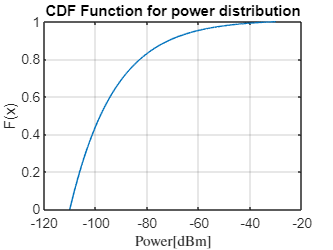

Pr_user = P0 - 10*n*log10(user_dist./d0);
cdfplot(Pr_user)
title("CDF Function for power distribution")
xlabel('Power[dBm]', 'Interpreter','latex' ...
    )

## Part2

    
$${\textrm{SNR}}^{\textrm{dB}} =P_r \left\lbrack \textrm{dBm}\right\rbrack -P_{\textrm{noise}} \left\lbrack \textrm{dBm}\right\rbrack$$


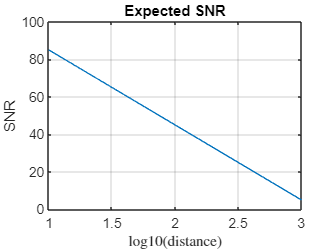

SNR = Pr_user - (Pnoise + 30);
figure
plot(log10(user_dist), SNR)
title("Expected SNR")
xlabel("log10(distance)", 'Interpreter','latex')
ylabel("SNR")
grid on 

## Part 3


$$P_r^{\left\lbrack \textrm{dBm}\right\rbrack } =P_0^{\left\lbrack \textrm{dBm}\right\rbrack } -10{\textrm{nlog}}_{10} \left(\frac{d}{d_0 }\right)+X^{\left\lbrack \textrm{dB}\right\rbrack } ;X~N\left(0,{25}^{\textrm{dB}} \right)$$


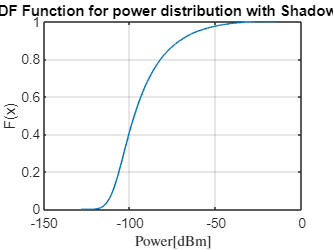

sigma_db = 5;
x_db = randn(numel(user_dist), 1)*sigma_db;
Pr_user_shdw = P0 - 10*n*log10(user_dist/d0) + x_db;
figure
cdfplot(Pr_user_shdw)
title("CDF Function for power distribution with Shadowing")
xlabel('Power[dBm]', 'Interpreter','latex' ...
    )

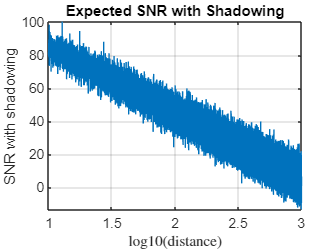


SNR_shdw = Pr_user_shdw - (Pnoise + 30);
figure
plot(log10(user_dist), SNR_shdw)
title("Expected SNR with Shadowing")
xlabel("log10(distance)", 'Interpreter','latex')
ylabel("SNR with shadowing")
grid on 

## Part 4


$$\begin{array}{l}
P_{\textrm{out}} =\Pr \left(\textrm{SNR}<{\textrm{SNR}}_{\min } \right)=\Pr \left(P_r -P_{\textrm{noise}} <P_{r_{\min } } -P_{\textrm{noise}} \right)=\\
\Pr \left(P_r <P_{r_{\min } } \right)=\Pr \left(P_0 -10{\textrm{nlog}}_{10} \left(\frac{d}{d_0 }\right)+X<{48}^{\textrm{dBm}} +P_{\textrm{noise}} \right)=\\
\Pr \left(X<{48}^{\textrm{dBm}} +P_{\textrm{noise}} -\left(P_0 -10{\textrm{nlog}}_{10} \left(\frac{d}{d_0 }\right)\right)\right)=1-Q\left(\frac{\left({48}^{\textrm{dBm}} +P_{\textrm{noise}}^{\textrm{dB}} -\left(P_0^{\textrm{dB}} -10{\textrm{nlog}}_{10} \left(\frac{d}{d_0 }\right)\right)\right)}{\sigma {\;}_{\textrm{dB}} }\right)
\end{array}$$


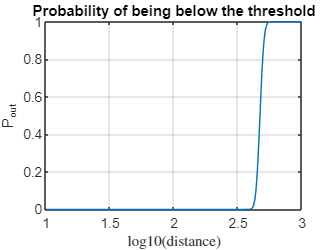

P_out = 1-qfunc((18 + 30) + Pnoise - (P0 - 10*n.*log10(user_dist/d0)));
figure
plot(log10(user_dist), P_out)
title("Probability of being below the threshold")
xlabel("log10(distance)", 'Interpreter','latex')
ylabel("P_{out}")
grid on

## Part 5

idx_min = min(find(SNR<=SNR_min));
min_rad = user_dist(idx_min);
min_Area = pi*(min_rad^2 - d0^2) % Minimum Area using simulation

min_Area = 7.0302e+05


$$\begin{array}{l}
C=Q\left(a\right)+e^{\frac{\left(2-2\mathrm{ab}\right)}{b^2 }} Q\left(\frac{\left(2-\mathrm{ab}\right)}{b}\right)\to a=\frac{\left(P_{r,\min } -P_r \left(D\right)\right)}{\sigma_{\mathrm{dB}} },b=\frac{\left(10{\mathrm{nlog}}_{10} \left(e\right)\right)}{\sigma {\;}_{\mathrm{dB}} }\\
P_{r,\min }^{\mathrm{dBm}} ={\mathrm{SNR}}_{\min }^{\mathrm{dB}} +P_{\mathrm{noise}}^{\mathrm{dBm}} \\
S=\pi \;D^2 C
\end{array}$$


a = (SNR_min + (Pnoise + 30) - Pr_user(end))/sigma_db

a = 2.6000

b = 10*n*log10(exp(1))/sigma_db

b = 3.4744

C = qfunc(a) + exp((2-2*a*b)/b^2)*qfunc((2 - a*b)/b)

C = 0.2632

min_Area_anl = pi*D^2*C

min_Area_anl = 8.2688e+05

# Q2


$$\begin{array}{l}
N=15\;;\textrm{Num}\;\textrm{of}\;\textrm{Multipath}\;\textrm{components}\\
\theta_n ~U\left(0,\frac{\pi }{2}\right);\textrm{channel}\;\textrm{phase}\;\textrm{delay}\;\\
\tau {\;}_n ~U\left\lbrack \left(1\mu \;s,10\mu \;s\right)\right\rbrack ;\textrm{channel}\;\textrm{delay}\\
\alpha {\;}_n ~\textrm{Rayleigh}\to P\left(\alpha \right)=\frac{\alpha }{\sigma {\;}^2 }\exp \left(-\frac{\alpha^2 }{2\sigma {\;}^2 }\right),2\sigma {\;}^2 =\tau {\;}^{-4} *{10}^{-3} \\
f_{D,n} =\frac{\nu \;}{\lambda \;}\cos \theta_n \to \phi {\;}_n \left(t\right)=\int_0^t 2\pi \;f_{D,n} \textrm{dt}=2\pi \;f_{D,n} t\;\\
c\left(t,\tau \;\right)=\sum_{n=1}^{15} \alpha_n e^{\left(-j\phi_n \right)} \delta \left(\tau -\tau {\;}_n \right)\;\\
\textrm{Wideband}\;\textrm{Fading}\to T>>\sigma {\;}_{\textrm{rms},\textrm{delay}\;\textrm{spread}} \\
\sigma_{\textrm{rms},\textrm{delay}\;\textrm{spread}} =\sigma_{U\left(\left\lbrack 1\mu \;s,10\mu \;s\right\rbrack \right)} =\frac{10-1}{2\sqrt{\;3}}=2\ldotp 598\mu \;s;\\
\frac{1}{B}\approx T<<\sigma {\;}_{\textrm{rms},\textrm{delay}\;\textrm{spread}} \to \sigma {\;}_{\textrm{rms},\textrm{delay}\;\textrm{spread}} =10T\;=\;2\ldotp 598\mu s\to \\
B\approx \frac{1}{0\ldotp 2598\mu s}=3\ldotp 85\;\textrm{MHz};\to f_{\textrm{sampling}} \approx 4\textrm{MHz}\\

\end{array}$$


fc = 3e9; % Widaband fading
f = 0:1e6;
N = 15; % Num of channels
n = 1e5; % Num of reapets
tau = unifrnd(1, 10, N, 1)*1e-6;
theta = unifrnd(0, pi/2, N, 1);
Power_avg = 1e-3 * (tau*1e6).^-4; % Average power of each path
sigma = sqrt(Power_avg/2); 
alpha = raylrnd(sigma); 
v = 30;
lambda = 3e8 / fc;

## Part1

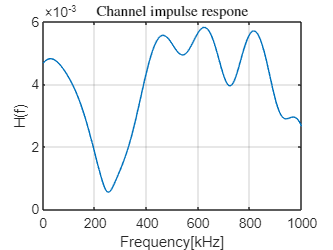

f_Dplr = v/lambda*cos(theta);
phi = 2*pi*(fc).*tau;
% H = zeros(numel(f), 1);
H = 0;
for i= 1:N
    H = H + alpha(i)*exp(-1j.*phi(i))*exp(-1j*2*pi.*f*tau(i));
end

figure
plot(f*1e-3, abs(H))
grid on
xlabel("Frequency[kHz]")
ylabel("H(f)")
title('Channel impulse respone','Interpreter','latex')

## Part 2

h_tot = 0;
for i = 1:n
    theta = unifrnd(0, pi/2, N, 1);
    Power_avg = 1e-3 * (tau*1e6).^-4; % Average power of each path
    sigma = sqrt(Power_avg/2); 
    alpha = raylrnd(sigma);
    f_Dplr = v/lambda*cos(theta);
    phi = 2*pi*(fc - f_Dplr).*tau;
    H = 0;
    for j = 1:N
        H = H + alpha(j)*exp(-1j.*phi(j));
    end
    h_tot = [h_tot ; H'*H];
end
channel_average = mean(h_tot)

channel_average = 3.1596e-05

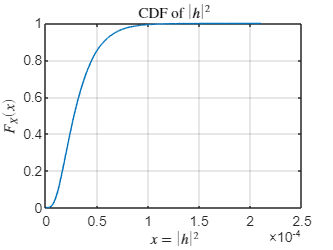

figure
cdfplot(h_tot)
xlabel('$x=|h|^2$','Interpreter','latex')
ylabel('$F_X(x)$','Interpreter','latex')
title('CDF of $|h|^2$','Interpreter','latex')

### Comparing CDFs

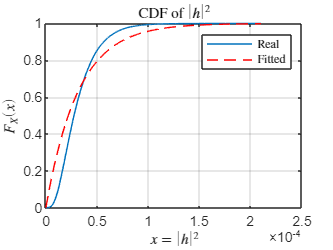

figure
cdfplot(h_tot);
hold on
plot(sort(h_tot), 1-exp(-sort(h_tot)/channel_average), 'r--');
xlabel('$x=|h|^2$','Interpreter','latex')
ylabel('$F_X(x)$','Interpreter','latex')
title('CDF of $|h|^2$','Interpreter','latex')
legend('Real', 'Fitted', 'Interpreter', 'latex')
hold off